# Crystal lattice image and distortion of that image (double)

By "double" I mean the data type. The first version had the inputs and outputs of lattices and Fourier things in uint8. Let's see how it improves if we use double instead of uint8.

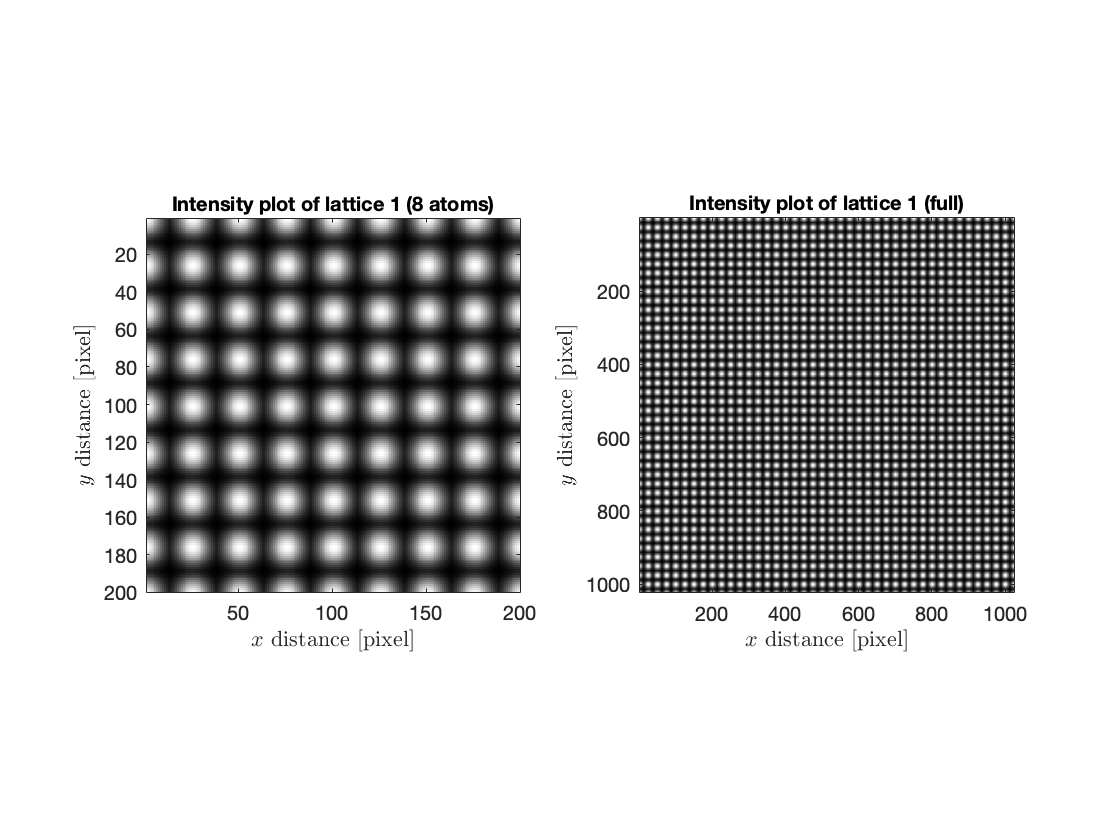

image_length = 1024;
image_height = 1024;
atom_radius = 25;

lat1 = createLattice(image_height,image_length,atom_radius,0.25);
comboPlot(normies(lat1),"lattice 1",atom_radius);

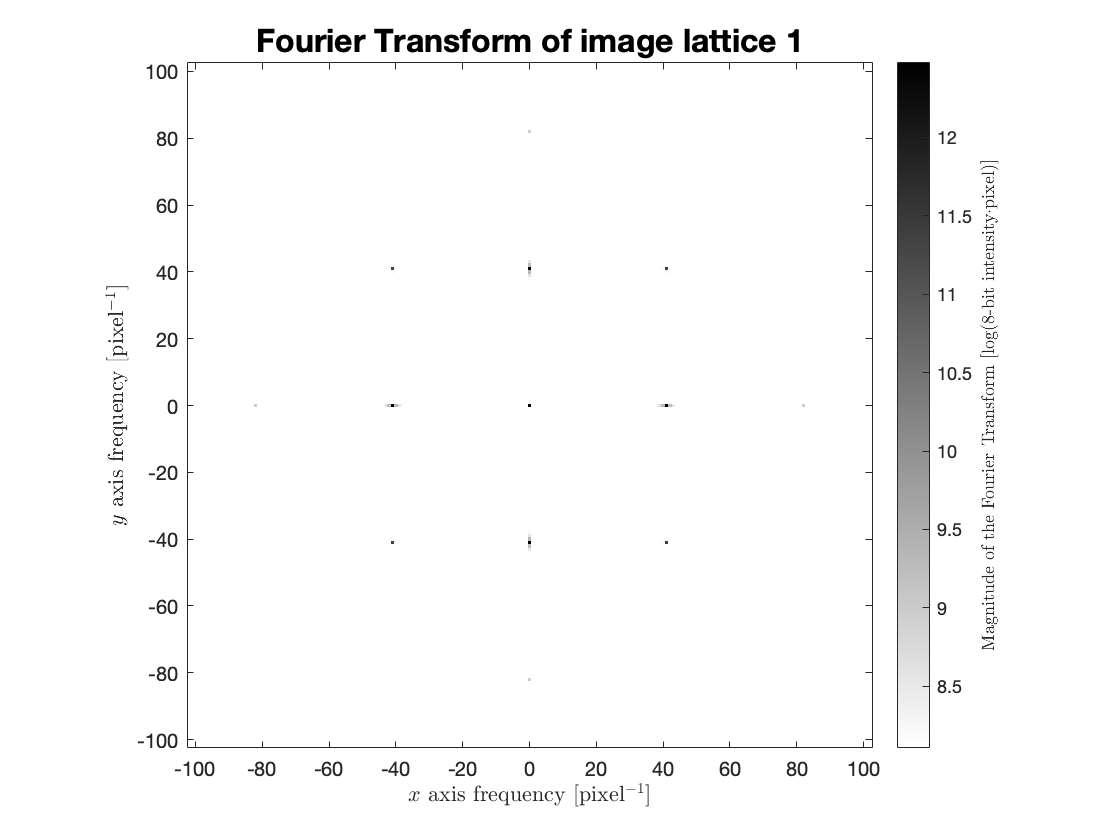

[lat1fft, Qx, Qy] = myFFT(lat1,"lattice 1");


% u = uCreate(image_height,image_length);
% 
Qx = [Qx; 0]*2*pi/image_length;
Qy = [0; Qy]*2*pi/image_height;

Okay, let's stop creating lattices with Gaussian atoms. Let's define lattices from $Q_x$ and $Q_y$ and $u=0$.

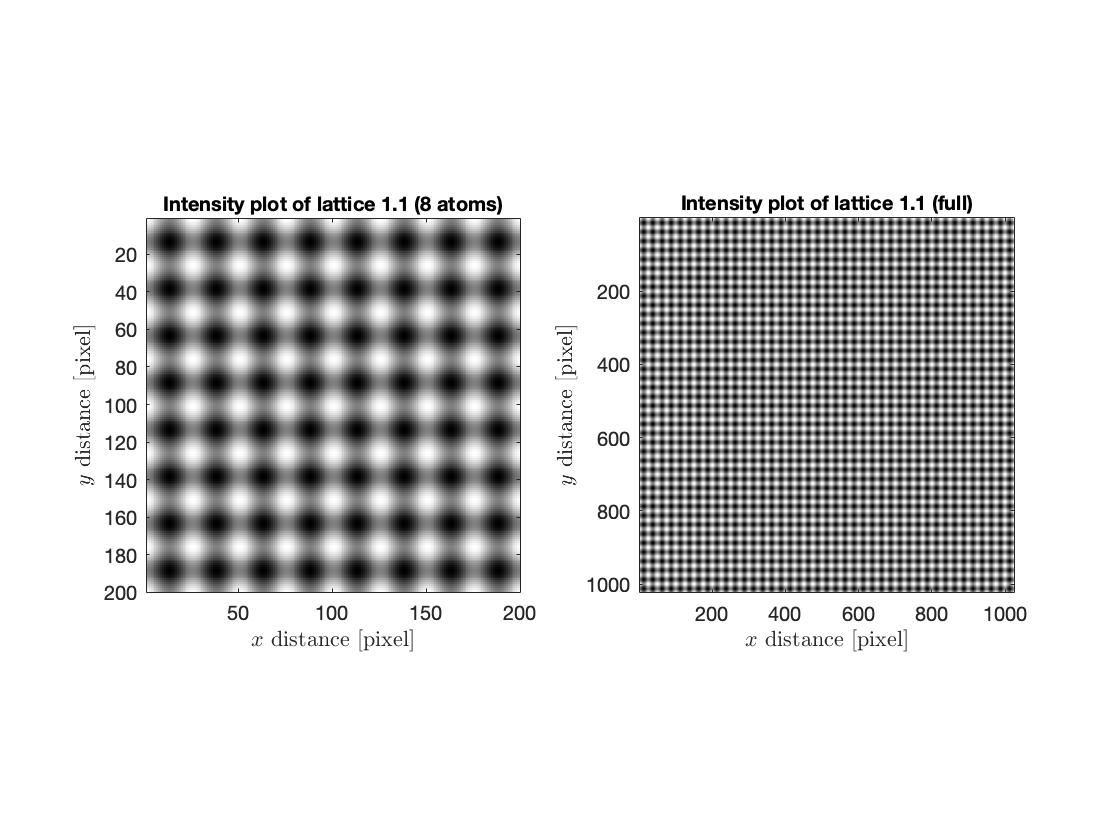

% perfect square lattice defined by having u = 0
lat1_1 = uTransform(ones(image_height,image_length),uCreate(image_height,image_length,0),Qx,Qy);
comboPlot(normies(lat1_1),"lattice 1.1",atom_radius);

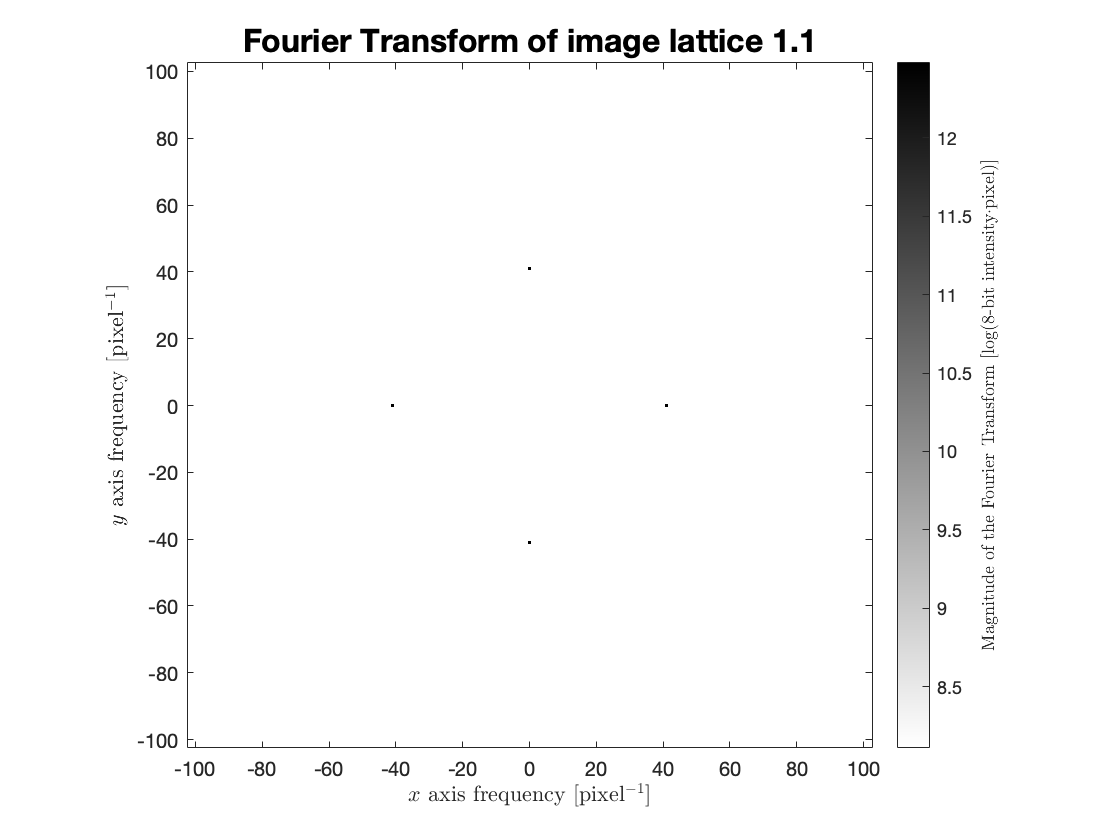

[lat1_1fft, Qx1, Qy1] = myFFT(lat1_1,"lattice 1.1");

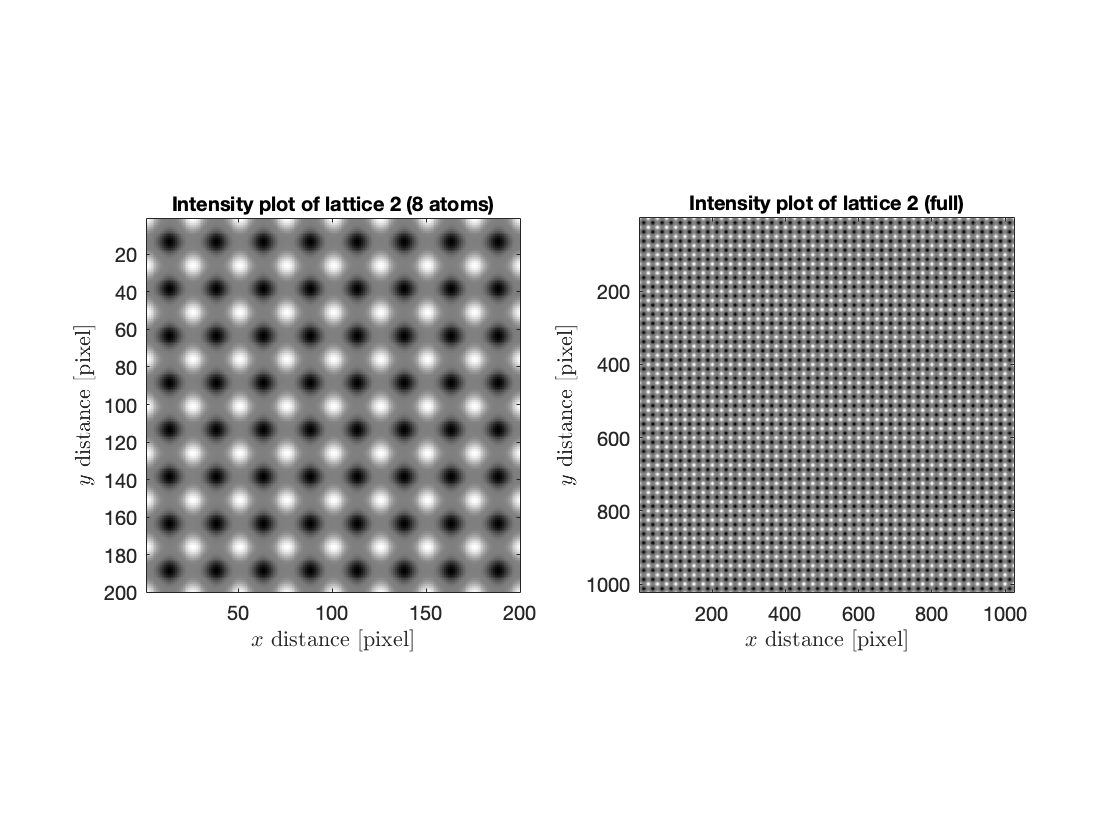


Qx = [Qx1; 0]*2*pi/image_length;
Qy = [0; Qy1]*2*pi/image_height;

u = uCreate(image_height,image_length,0); % add a parameter '0' to set u = 0

lat2 = uTransform(lat1_1,-u,Qx,Qy);
comboPlot(normies(lat2),"lattice 2",atom_radius);

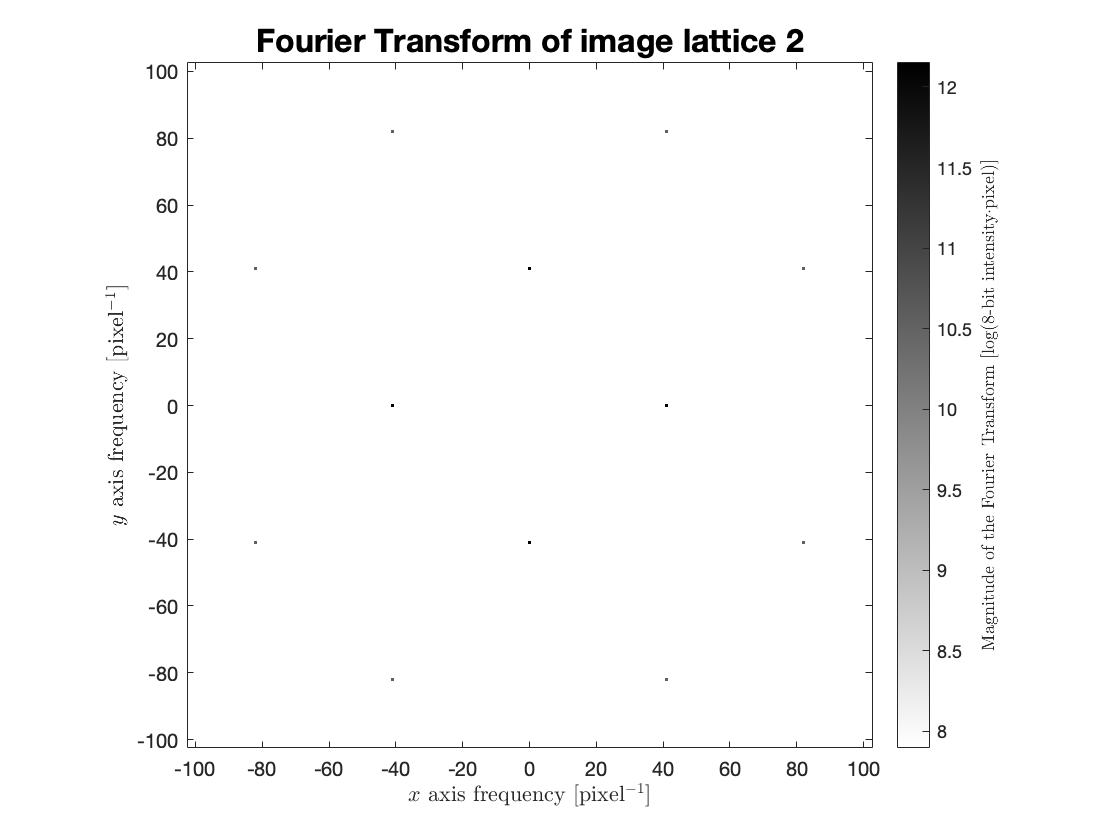

lat2fft = myFFT(lat2,"lattice 2");

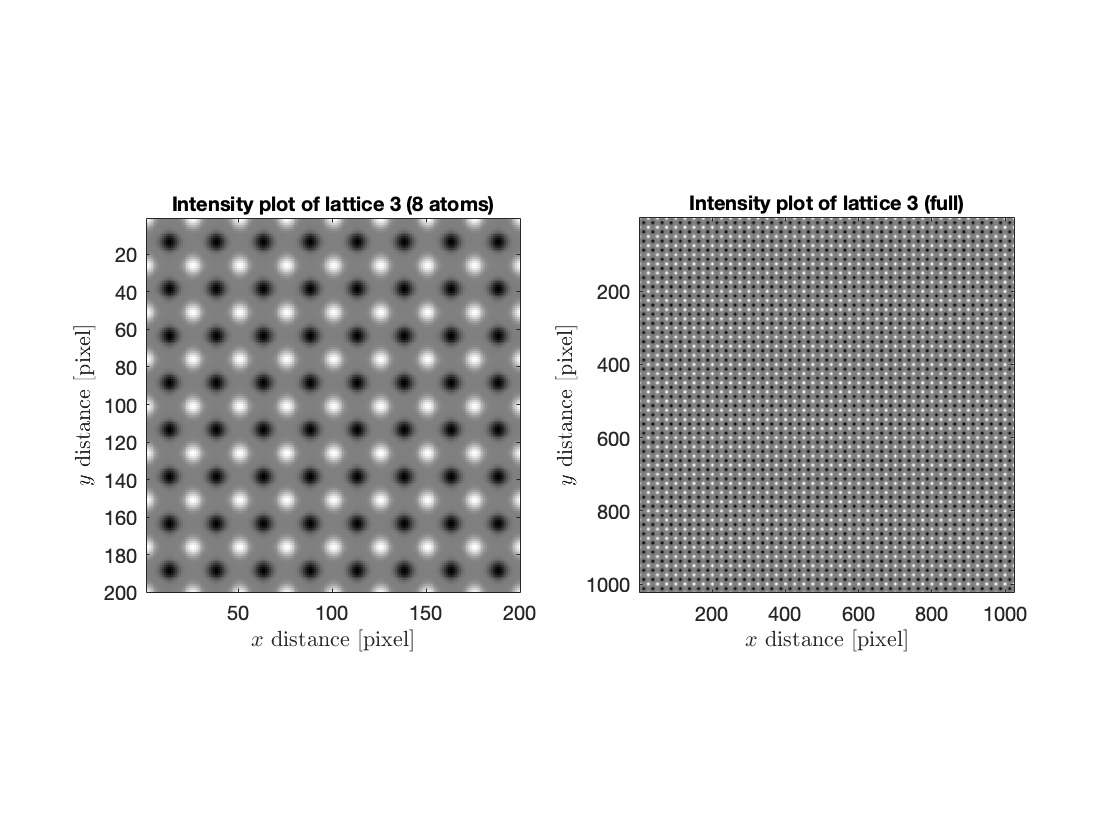


lat3 = uTransform(lat2,u,Qx,Qy);
comboPlot(normies(lat3),"lattice 3",atom_radius);

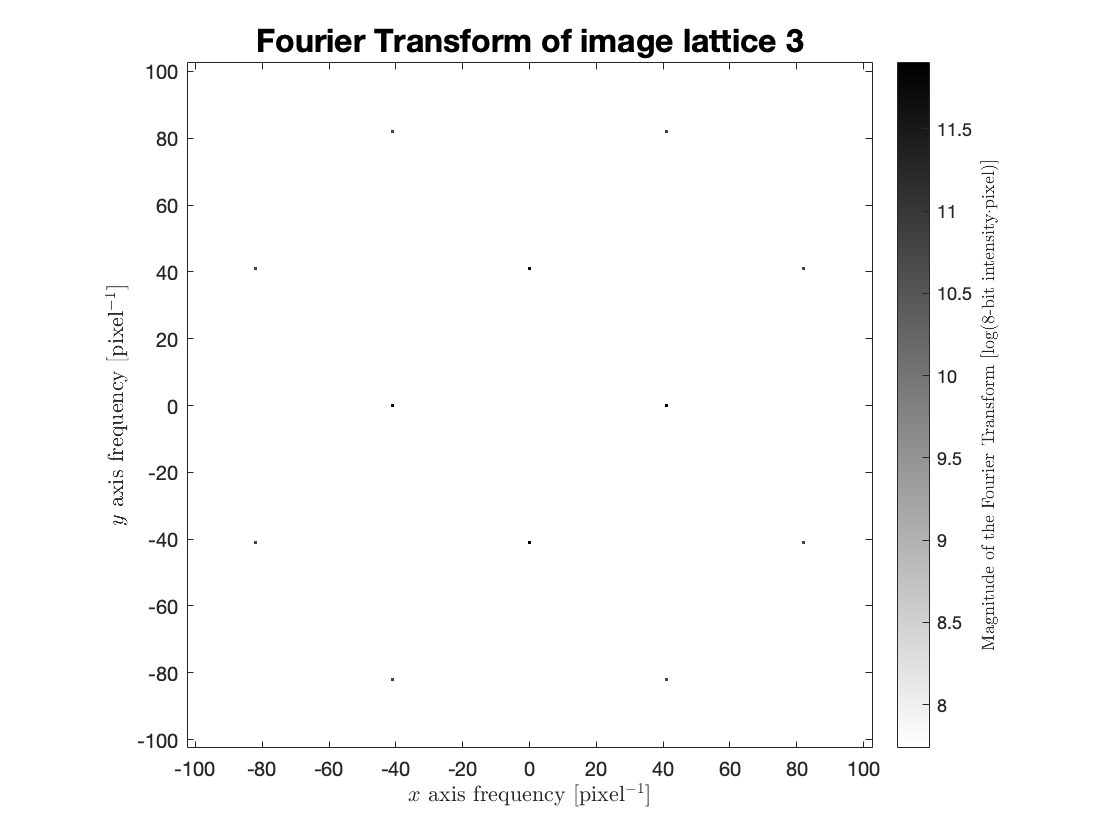

lat3fft = myFFT(lat3,"lattice 3");

It doesn't work as I expected. Applying $u$ multiple ($n$) times to a perfect square lattice defined by setting $u=0$ is equivalent to taking $\left(\text{cos}(x)+\text{cos}(y)\right)^{n+1}$. And that's why the frequency is twice as much for an odd $n$ and the atoms look thinner with increasing $n$.

## Functions

I can totally declare all these in separate files for further practice. But I'm scared. Also, in the meantime, there might be a multitude of adjustments to the functions that jumping through multiple files would be tiresome and annoying.

function u1 = uCreate(h,l, scale_mag)
    % just to avoid clutter
    u1 = zeros(h,l,2);

    scale_coor = 1; % to scale the coordinates of the vector field
    if nargin<3
        scale_mag = 15; % to scale the magnitude of the vectors in the vector field
    end
    [v,w] = meshgrid(1:l,1:h);
    x = scale_coor.*(v-l/2)./l.*2.*pi;
    y = scale_coor.*(w-h/2)./h.*2.*pi;
    for k = 1:h
        for l = 1:l
            u1(k,l,1) = cos((y(k,l)))*scale_mag;
            u1(k,l,2) = -x(k,l)*sin(y(k,l))*scale_mag;
        end
    end
    
%     skipx = 50*l/1024;
%     skipy = 50*h/1024;
%     x = x(1:skipx:end,1:skipy:end);
%     y = y(1:skipx:end,1:skipy:end);
%     
%     quiver(v(1:skipx:end,1:skipy:end).*scale_coor,w(1:skipx:end,1:skipy:end).*scale_coor, ...
%         cos(y),-x.*sin(y));
%     t = title("Vector field $u$","Interpreter","latex");
%     xlabel("$x$ distance [pixel]","Interpreter","latex");
%     ylabel("$y$ distance [pixel]","Interpreter","latex");
%     set(gca,"YDir","reverse");
%     axis equal tight;
%     t.FontSize = 16;
    
end

function A = normies(A, lim)
    % I'm creating this function cuz MATLAB's normalize() is dumb
    if nargin<2
        lim = [0 1];
    end
    A = lim(1)+(A-min(A,[],"all"))./(max(A,[],"all")-min(A,[],"all")).*(lim(2)-lim(1));
end
    
function P = createLattice(l, h, r, rel_std)
    % l, h are dimensions; r, rel_std specify the atom radius and spacing
    % nm is the title

    % create the atom just like in 1.1
    atom = fspecial("gaussian",r,rel_std*r);
    
    % create the lattice
    P = zeros(l, h, "double");
    for i = 1:l
        for j = 1:h
            P(i,j) = atom(mod(i-1+floor(r/2),r)+1,mod(j-1+floor(r/2),r)+1);
        end
    end
    P = normies(P, [-1 1]);
end

function [] = latticePlot(P0,nm1,r,num)
    % P0 is the image (uint8); nm1 is the title; r, num specify the view
    
    imagesc(P0, [0 1]); % change the limits if you want
                        % to plot double or logical values
    colormap(gray);
    axis equal tight
    if nargin<4
        num = 8;
        if nargin>2
            xlim([1 r*num]);
            ylim([1 r*num]);
        end
    else
        xlim([1 r*num]);
        ylim([1 r*num]);
    end
    
    xlabel("$x$ distance [pixel]","Interpreter","latex");
    ylabel("$y$ distance [pixel]","Interpreter","latex");
    t = title("Intensity plot of " + nm1);
    t.FontSize = 10;
end

function [] = comboPlot(P0, nm, a)
    figure;
    subplot(1,2,1);
    latticePlot(P0,nm + " (8 atoms)",a,8);
    subplot(1,2,2);
    latticePlot(P0,nm + " (full)");
    figure;
end

function [Q, idx, idy] = myFFT(P, nm, dip)
    % P is the image; r, n, noisy specify the colorbar range
    % Q is the fft; idx, idy are the indices of Qx, Qy
    
    sp = size(P);
    Q = fft2(P);
    Q1 = log(abs(Q));
    Q2 = Q1;
    Q2(isinf(Q2)) = nan;
    [~,idx] = max(Q2(2:end,1),[],"omitnan");
    [~,idy] = max(Q2(1,2:end),[],"omitnan");
%     idx = idx + 1;  % to make up for the omitted first index
%     idy = idy + 1;
    
    Q1 = fftshift(Q1);
    
    if nargin<3
        dip = [0.65 1];
    end
    
    sec_max = min(maxk(max(Q1),2)); % for scaling the colorbar
    imagesc(-sp(1)/2,-sp(2)/2,Q1, sec_max*dip);
    colormap(flipud(gray));
    set(gca,"YDir","normal");
    axis equal tight
    c = colorbar;
    
    xyl = max(idx,idy);
    xlim([-xyl*2.5 xyl*2.5]); % comment these to view whole Fourier transform
    ylim([-xyl*2.5 xyl*2.5]);
    xlabel("$x$ axis frequency [pixel$^{-1}$]","Interpreter","latex");
    ylabel("$y$ axis frequency [pixel$^{-1}$]","Interpreter","latex");
    c.Label.String = "Magnitude of the Fourier Transform [log(8-bit intensity$\cdot$pixel)]";
    c.Label.Interpreter = "Latex";
    t = title("Fourier Transform of image " + nm);
    t.FontSize = 16;
end

function P2 = uTransform(P1, u1, qx1, qy1)
    % P1 is the image; u1 is the displacement vector field
    % qx1, qx2 are the modulation wavevectors
    sp = size(P1);
    P2 = zeros(sp(1),sp(2), "double");
    for i = 1:sp(2)
        for j = 1:sp(1)
            % notice the flipped coordinates to accomodate for row:y;column:x
            P2(j,i) = abs(P1(j,i))*(cos(qx1'*([i-1;j-1]-[u1(j,i,1); u1(j,i,2)])) ...
                +cos(qy1'*([i-1;j-1]-[u1(j,i,1); u1(j,i,2)])))/2; % note the half
        end
    end
end